# Week 4: Data Analysis Applicaton on Dark Triad Personality Traits

## About the Dataset

The dark triad is a term in psychology used to refer to the traits of Machiavelianism, Narcissism,and Psychopathy. 

- Machiavelianism is charactarized by manipulation of others for one's own gain

- Narcissism means having a inflated sense of self esteem and self-gradiosity

- Psychopathy is similar to antisocial personality disorder, which is often described as lacking a concience, and also has the charactaristics of impulsivity and selfishness

People scoring high on these tests are more likely to do things that hurt society. 

Link to research paper asociated with this survey:

[http://pdfs.semanticscholar.org/d667/3107caa8f90263a28447df5d428c298e08b5.pdf?source=post_elevate_sequence_page---------------------------](http://pdfs.semanticscholar.org/d667/3107caa8f90263a28447df5d428c298e08b5.pdf?source=post_elevate_sequence_page---------------------------)

## The Main Question

The goal of my work in this notebook is to validate the personality test. The question is: Do scores on each of the questions for sections of the dark triad correlate with each other? 

If the test is not a good measure of the traits, scoring highly on one question about Nacissism will not correlate with scoring highly on another question about Narcissism. This is the null hypothesis.

If the test is a good measure of traits, scoring highly on one question measuring Nacissism will correlate with scoring highly on another question about Narcissism. This is the alternative hypothesis. 

## Possible Secondary Questions

I would also want to see how much the dark triad personality traits correlate with each other. For example, if someone scores high in Psychopathy, are they also likely to score highly in Machiavelianism? And which traits correlate most highly with each other? Or are they independent?

There is also a datapoint for what country people came from, so it might be interesting to look at dark triad scores by country. The other extra piece of data is where they came from the test from (google search, main page of website), so I could do some analysis to see if there are any correlations bethween those factors. 

## Answering the Question

First do Pearson Correlation Coefficeint

Then try linear regression if time allows

data = readtable('data.csv');

size(data)

ans =        18192          29


average(data.M1)

ans = 4.1790

average(data.N1)

ans = 3.2695

average(data.P1)

ans = 3.0660

### Make data more useful

The questions for this dataset do not translate directly into scores for the traits in question. For exaple, the Narcissm section contains both statements such as: "I am an average person" and "Many group activities tend to be dull without me", which participants are asked to agree or disagree with. People who agree with the statment "Many group activities tend to be dull without me" would probably disagree with the statement "I am an average person", and vice versa. Agreeing with one statment would indicate high narcissism while agreeing with another would indicate low narcissism. I had to figure out a way to take this fact into account in order to do a good analysis of the data.

I looked up the name of the poster where this research was presented, and found a document that contained the methods that the researchers used to analysze the data. They simply reversed the scores on some of the questions, which were marked with "R." [http://www.midss.org/sites/default/files/d3.pdf](http://www.midss.org/sites/default/files/d3.pdf)

I decided to copy their method. 

The data was collected on a 5 point scale where 

1: Strongly Disagree

2: Disagree

3: Neither Agree nor Disagree

4: Agree

5: Strongly Agree

They did not state this, but there are some zeroes in the data. I assumed that these zeroes were outliers and removed them. 

% select only numeric data from table
n = vartype('numeric');
d = data(:, n);

% turn numeric data into array
da = table2array(d);
clear n d

% select only data from questions
da = da(:, 1:27);
size(da)

ans =        18192          27


Remove all entries with zeros (which means they did not answer)

[rows, ~] = find(da == 0); % find row values of 0 answers
size(rows) % confirm it is a reasonable number to just delete

ans =    748     1


da(rows, :) = []; % set rows with 0 in them to blank (delete them)
size(da)

ans =        17740          27


min(da)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


clear rows

Reverse value of questions for certain columns 

% (=columns N2, N6, N8, P2, P7)
% in array: 11, 15, 17, 20, 25
da(1:5, 11)

ans =      4
     5
     5
     1
     4


reverse = [11, 15, 17, 20, 25];
for i = 1:size(reverse)
    % for each string in the array "reverse", multiply all entries by 
    % -1, then add 6 (to reverse them) 
    da(:, reverse(i)) = (da(:, reverse(i)) *-1) + 6;
end
da(1:5, 11)

ans =      2
     1
     1
     5
     2


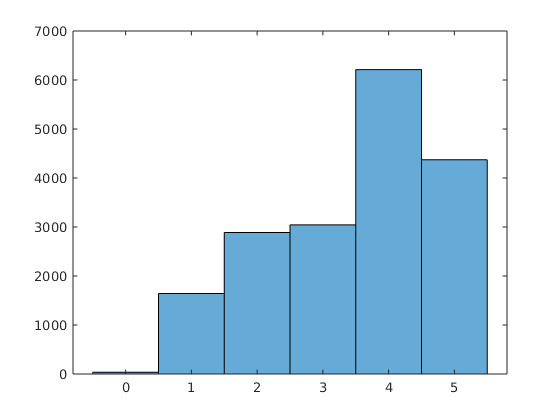

histogram(data.M2)

### Pearson Correlation Coefficeint

% tests if data is normally distributed (1 is yes)
h = lillietest(data.M1)

h = 1

Let's see how this works by finding the correlation between the average of two questions with the average of two other questions, and plotting it

R = corrcoef(((data.M1+data.M2)/2), ((data.M3+data.M4)/2))

R =     1.0000    0.5150
    0.5150    1.0000


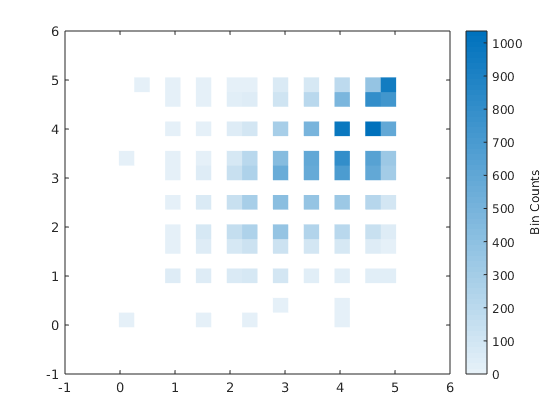

binscatter(((data.M1+data.M2)/2), ((data.M3+data.M4)/2))

There is a mid-level correlation. The data are not very highly correlated, but they are a lot better than random. Now I will compare more of the data. 

#### Compare each question to its neighbor

This block of code runs a for loop to compare each question to its neighbor without comparing between sections

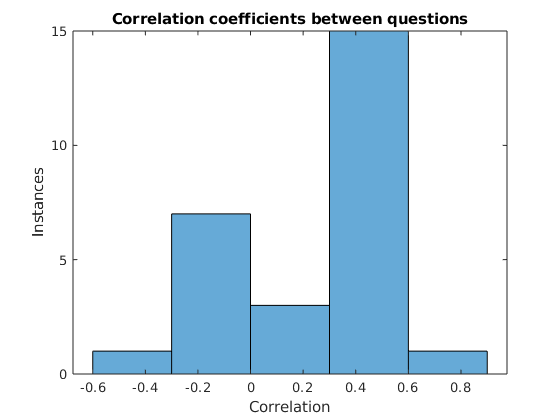

i = 1;
cArray = zeros(1, 27);

for i = 1:8 %M
    c = corrcoef(da(:, i), da(:, i+1));
    cArray(i) = c(2);
end

for i = 9:17 %N
    c = corrcoef(da(:, i), da(:, i+1));
    cArray(i) = c(2);
end

for i = 18:26 %C
    c = corrcoef(da(:, i), da(:, i+1));
    cArray(i) = c(2);
end

histogram(cArray)
ylabel("Instances");
xlabel("Correlation Coefficient")
title("Correlation coefficients between questions")

average(cArray)

ans = 0.1767

This method shows a not particuarly strong, but positive overall correlation, with some much more highly correlated questions.

#### Split Halves

[https://explorable.com/internal-consistency-reliability](https://explorable.com/internal-consistency-reliability)

This website said that a commonly used tests is to split the data in half and find the correlation of each half.

oddM = cat(2, da(:, 1), da(:, 3), da(:, 5), da(:, 7), da(:, 9));
avgOddM = mean(oddM, 2);
evenM = cat(2, da(:, 2), da(:, 4), da(:, 6), da(:, 8));
avgEvenM = mean(evenM, 2);
oddN = cat(2, da(:, 11), da(:, 13), da(:, 15), da(:, 17));
avgOddN = mean(oddN, 2);
evenN = cat(2, da(:, 10), da(:, 12), da(:, 14), da(:, 16), da(:, 18));
avgEvenN = mean(evenN, 2);
oddP = cat(2, da(:, 19), da(:, 21), da(:, 23), da(:, 25), da(:, 27));
avgOddP = mean(oddP, 2);
evenP = cat(2, da(:, 20), da(:, 22), da(:, 24), da(:, 26));
avgEvenP = mean(evenP, 2);

Find correlations between halves and plot

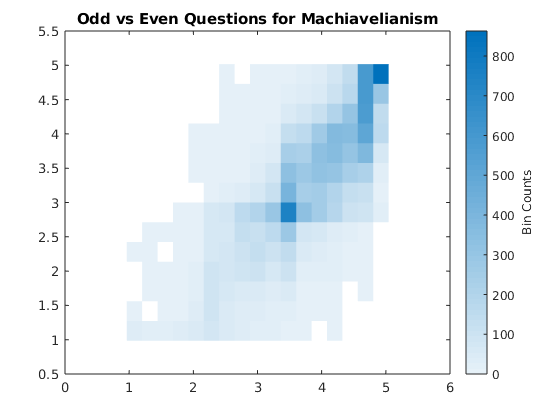

binscatter(avgOddM, avgEvenM)
title("Odd vs Even Questions for Machiavelianism")

corrcoef(avgOddM, avgEvenM)

ans =     1.0000    0.7939
    0.7939    1.0000


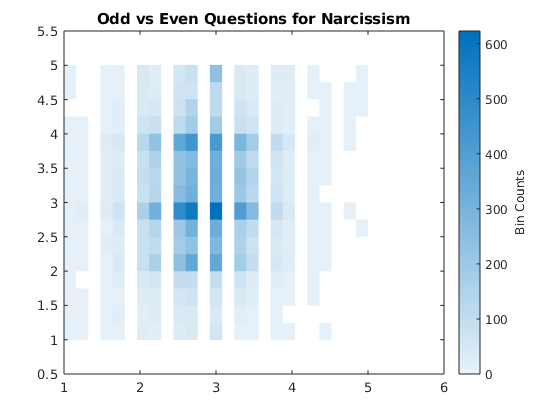


binscatter(avgOddN, avgEvenN)
title("Odd vs Even Questions for Narcissism")

corrcoef(avgOddN, avgEvenN)

ans =     1.0000    0.0572
    0.0572    1.0000


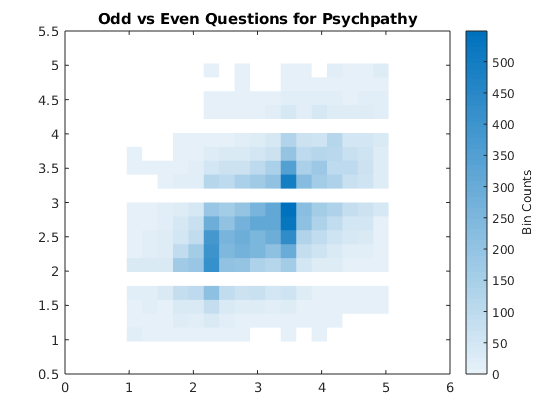


binscatter(avgOddP, avgEvenP)
title("Odd vs Even Questions for Psychpathy")

corrcoef(avgOddP, avgEvenP)

ans =     1.0000    0.5168
    0.5168    1.0000


The Machiavelianism questions seem to correlate highly. The Narcissism questions have a very low correlation, and the correlation for Psychopathy is medium.

This test would suggest that the questions for Machiavelianism are very good, the questions for Psycopathy are good, and the questions for Narcissism are not very helpful. However a test can be measured by both tests like these, and predictive validity. I don't have any information about predictive validity, so I can't analyze that part. 

#### Out of Curiosity: What traits correlate with each other?

corrcoef(avgOddM, avgEvenN)

ans =     1.0000    0.5379
    0.5379    1.0000


corrcoef(avgOddN, avgEvenP)

ans =     1.0000   -0.0088
   -0.0088    1.0000


corrcoef(avgOddP, avgEvenN)

ans =     1.0000    0.4775
    0.4775    1.0000


corrcoef(avgOddP, avgEvenM)

ans =     1.0000    0.6815
    0.6815    1.0000


#### Comfirmatory Factor Analysis

NINJA hours: ask what confirmatory factor analysis outputs, and figure out if something is wrong with my avgOddN

[https://www.mathworks.com/help/stats/factoran.html](https://www.mathworks.com/help/stats/factoran.html)

[Lambda,Psi,T,stats,F] = factoran(da,1)

Lambda =     0.4401
    0.7548
    0.6536
    0.3674
    0.7556
    0.7004
    0.4672
    0.6595
    0.6343
    0.3747


Psi =     0.8063
    0.4303
    0.5728
    0.8650
    0.4290
    0.5095
    0.7817
    0.5650
    0.5976
    0.8596


T = 1

stats = struct with fields:
    loglike: -2.1936
        dfe: 324
      chisq: 3.8889e+04
          p: 0


F =     0.2943
   -1.6389
   -1.3084
    2.0118
    0.0395
   -0.8021
    0.3394
    1.5911
    0.0413
    2.1547


% but what does it actually mean?

### K-Means Clustering 

I did not really get this to work with the data

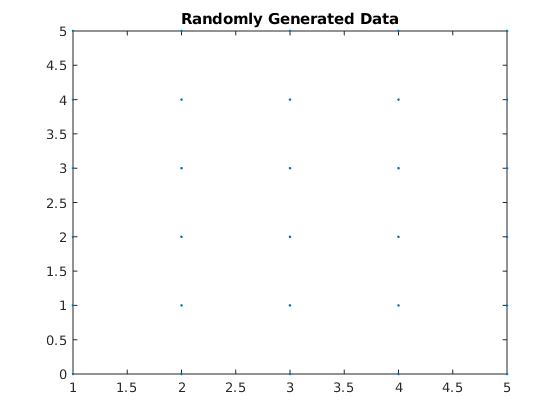

rng default; % For reproducibility
M = da(:, 1:9);
M = M(:);
N = da(:, 10:18);
N = N(:);
P = da(:, 19:27);
P = P(:);

% trying to see if M and N scores cluster differently
X = [M, N];

figure;
plot(X(:,1),X(:,2),'.');
title 'Randomly Generated Data';

opts = statset('Display','final');
[idx,C] = kmeans(X,2,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 1 iterations, total sum of distances = 259644.
Replicate 2, 1 iterations, total sum of distances = 231440.
Replicate 3, 1 iterations, total sum of distances = 284010.
Replicate 4, 2 iterations, total sum of distances = 246254.
Replicate 5, 2 iterations, total sum of distances = 263316.
Best total sum of distances = 231440


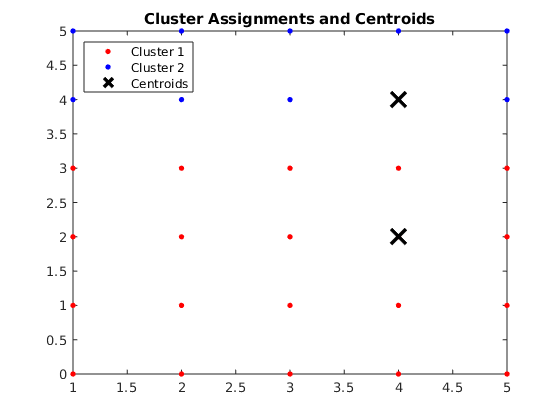


figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off;

% hmm, not sure how to interpret this